**Finite Difference Methods for Elliptic PDEs**

Poisson Equations


$$-\Delta u = f$$


in FD scheme( Replacing the dervatives by finite differences )


$$-\left( \frac{u_{i-\text{1,}j}-2u_{i,j}+u_{i+\text{1,}j}}{\Delta x^2}+\frac{u_{i,j-1}-2u_{i,j}+u_{i,j+1}}{\Delta y^2} \right) =f_{i,j}
$$


in tensor product form( with quadrilateral mesh )

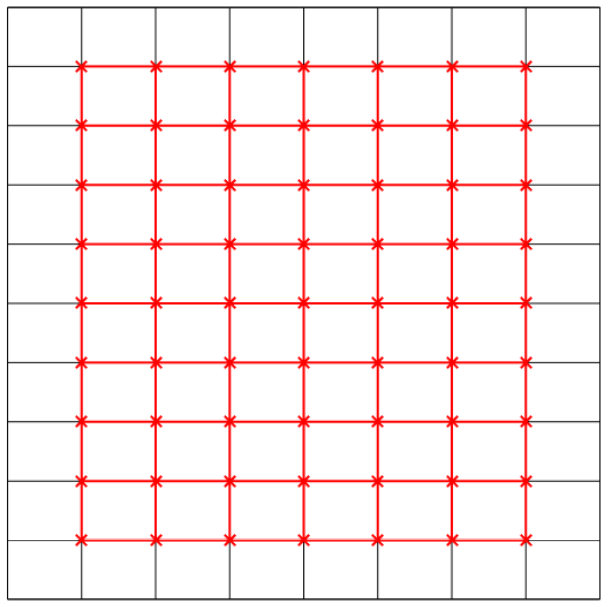


$$\left( A_1\otimes I_N+I_M\otimes A_2 \right) \mathbf{u}=\mathbf{f}$$


where


$$A_{1}=\frac{1}{\Delta x^2}\left[\begin{array}{cccc}{2} & {-1} & {} & {} \\ {-1} & {2} & {-1} & {} \\ {} & {\ddots} & {\ddots} & {\ddots} \\ {} & {} & {-1} & {2}\end{array}\right]_{M \times M}A_{2}=\frac{1}{\Delta y^2}\left[\begin{array}{cccc}{2} & {-1} & {} & {} \\ {-1} & {2} & {-1} & {} \\ {} & {\ddots} & {\ddots} & {\ddots} \\ {} & {} & {} & {-1} & {2}\end{array}\right]_{N \times N}$$



$$\mathbf{u}=\left[u_{11}, u_{12}, \ldots, u_{1 N}, u_{21} \ldots, u_{2 N}, \ldots, u_{M 1}, \ldots u_{M N}\right]^\text{T}$$



$$\mathbf{f}=\left[f_{11}, f_{12}, \ldots, f_{1 N}, f_{21} \ldots, f_{2 N}, \ldots, f_{M 1}, \ldots f_{M N}\right]^\text{T}$$


error_Max_norm


$$\left\|\mathbf{u}-\mathbf{au}\right\|_{\infty}$$


error_L2_norm


$$\sqrt{\left( \Delta x \right) \left( \Delta y \right) \left( \mathbf{u}-\mathbf{au} \right)^\text{T}\left( \mathbf{u}-\mathbf{au} \right)}

$$


close, clear, clc
digits(128);

bx = [0, 1];
by = [0, 1];
N_x = 16;
N_y = N_x;


$$u(x,y) =e^{\left( \frac{1}{2}-x \right) ^2}+e^{\left( \frac{1}{2}-y \right) ^2}
$$


% tic
% Au1 = @(x, y)(exp((1/2 - x).^2) + exp((1/2 - y).^2));
% f1 = @(x, y)(- 2*exp((x - 1/2)^2) - 2*exp((y - 1/2)^2) - exp((x - 1/2)^2)*(2*x - 1)^2 - exp((y - 1/2)^2)*(2*y - 1)^2);
% u11 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x, N_y, Au1, f1, 1 );
% u12 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x, N_y, Au1, f1, 2 );
% toc


$$u(x+y) = \sin(x+y)$$


% tic
% Au3 = @(x, y)(sin(x+y));
% f3 = @(x, y)(2*sin(x + y));
% u21 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x, N_y, Au2, f2, 1 );
% u22 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x, N_y, Au2, f2, 2 );
% toc


$$u\left( x,y \right) =\sin \left( x\left( x-1 \right) \right) \sin \left( y\left( y-1 \right) \right) $$


Error_Max_norm: 0.00886732
Error_L2_norm: 0.0051797

ans =     0.0061    0.0060    0.0060    0.0059    0.0059    0.0059    0.0060    0.0060    0.0061
    0.0085    0.0082    0.0080    0.0079    0.0079    0.0079    0.0080    0.0082    0.0085
    0.0069    0.0062    0.0060    0.0059    0.0059    0.0059    0.0060    0.0062    0.0069


Subscripted assignment dimension mismatch.

Error in error_mesh (line 76)
            U2(:,2:end-1) = reshape(N_u(n1+1:n1+n2), index_y, nn)

Error in Poisson_2D_FD_rectangle_dirichlet (line 57)
        error_mesh( Au, N_m, N_u, A_u, N_x, N_y, XX, YY, index_y, Mesh)

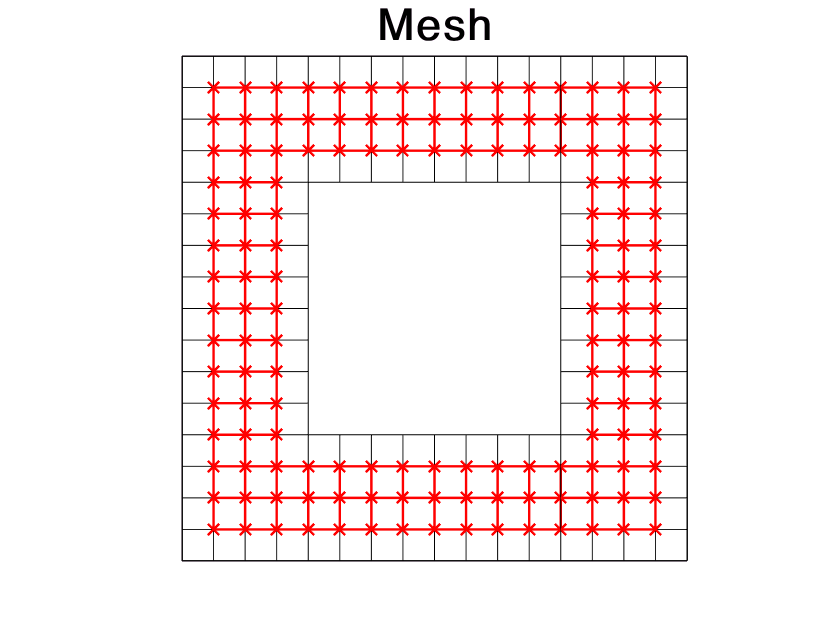

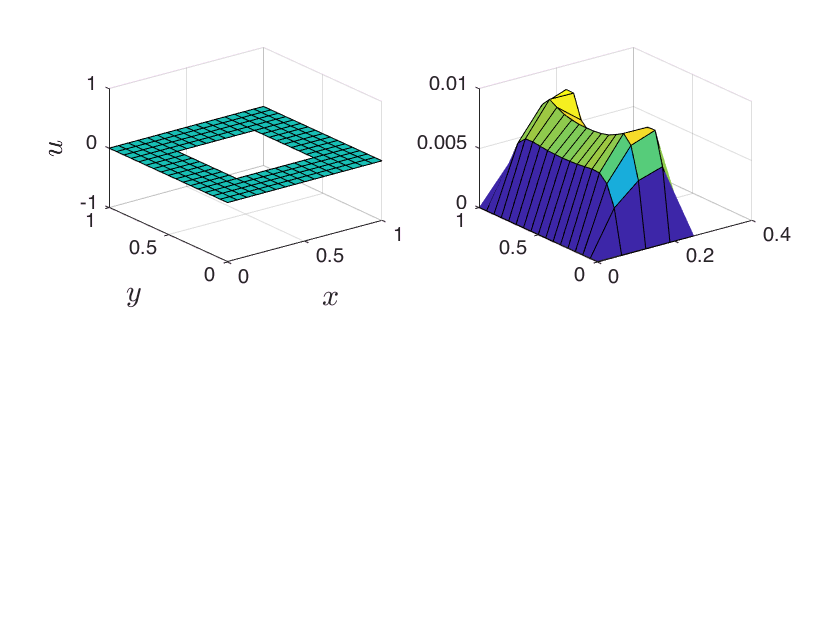

tic
% Au3 = @(x, y)(sin(x.*(x-1)).*sin(y.*(y-1)));
% f3 = @(x, y)(sin(x*(x - 1))*sin(y*(y - 1))*(2*x - 1)^2 - 2*cos(y*(y - 1))*sin(x*(x - 1)) - 2*cos(x*(x - 1))*sin(y*(y - 1)) + sin(x*(x - 1))*sin(y*(y - 1))*(2*y - 1)^2);
Au3 = @(x, y)((x+y)*0 );
f3 = @(x, y)((x+y)*0 + 1);


% disp(' h = 1/64')
% u31 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x, N_y, Au3, f3, 1 );
% u32 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x, N_y, Au3, f3, 2 );
u33 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x, N_y, Au3, f3, 3 );

% u311 = reshape(u31, 63, 63);
% u312 = u311(8:8:end-7,8:8:end-7);
% u313 = reshape(u312, size(u312, 1)^2, 1);
% disp(' h = 1/32')
% u32 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x/2, N_y/2, Au3, f3, 1 );
% u321 = reshape(u32, 31, 31);
% u322 = u321(4:4:end-3,4:4:end-3);
% u323 = reshape(u322, size(u322, 1)^2, 1);
% disp(' h = 1/16')
% u33 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x/4, N_y/4, Au3, f3, 1 );
% u331 = reshape(u33, 15, 15);
% u332 = u331(2:2:end-1,2:2:end-1);
% u333 = reshape(u332, size(u332,1)^2, 1);
% disp(' h = 1/8')
% u34 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x/8, N_y/8, Au3, f3, 1 );
% u = [u313, u323, u333, u34]

% u321 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x, N_y, Au3, f3, 2 );
% u322 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x/2, N_y/2, Au3, f3, 2 );
% u323 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x/4, N_y/4, Au3, f3, 2 );
% u324 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x/8, N_y/8, Au3, f3, 2 );

toc